# Amplitudenquantisierung

#### Signal- und Messwertverarbeitung 

h_da, fbeit

**History**:

- Version 1.1: Initial Version, Darmstadt, 08.05.2023,  C. Jakob 

Some clean-up and basic configurations at startup

clear; close all; clc;
set(groot, 'defaultTextInterpreter', 'LaTeX');
set(groot, 'DefaultAxesTickLabelInterpreter', 'LaTeX');
format long; 

**Things to explore:**

- Change bitwidth, start with 3, ...

- Change dynamic range of the signal - impact on quantization 

f0 = 1;
T0 = 1/f0;
A0 = 0.95;

S  = 10;                % Überabtastung - Anzahl der Abtastzeitwerte pro Signalperiode
fs = S*f0;              % Abtastfrequenz [Hz]
Ts = 1/fs;              % Abstastperiode [s]


bits = 100;

P   = 5;              % Anzahl der zu betrachtenden Signalperioden
T   = P/f0;             % und hieraus resultierender Zeitbereich
dt  = 1e-5;             % Zeitliche 'Auflösung' des kontinurilichen Signals ... 
N   = round(T0/dt);     % Anzahl der Intervalle pro Periode

t   = 0:dt:T-dt; 
s   = A0*sin(2*pi*f0*t);    

FR  = A0*2;

sq  = round(s*2^(bits-1)) / 2^(bits-1);  % round vs. floor
qe  = s-sq;                              % quantization error     
qs  = FR/2^(bits);                       % quantization step: fullrange/intervals



$$SQNR = \frac{P_S}{P_N}=\frac{\frac{1}{N} \sum_{n=0}^{N-1}s^{2}(n)}{\frac{1}{N} \sum_{n=0}^{N-1}e_{q}^{2}(n)}} $$
 
$$= \frac{\sum_{n=0}^{N-1}s^{2}(n)}{\sum_{n=0}^{N-1}e_{q}^{2}(n)}}
$$


sqnr   = 10*log10(sum(s.^2)/sum(qe.^2))

sqnr =      6.501762677449790e+02


sqnr_c = 1.76 + 6.02 * bits

sqnr_c =      6.037600000000000e+02


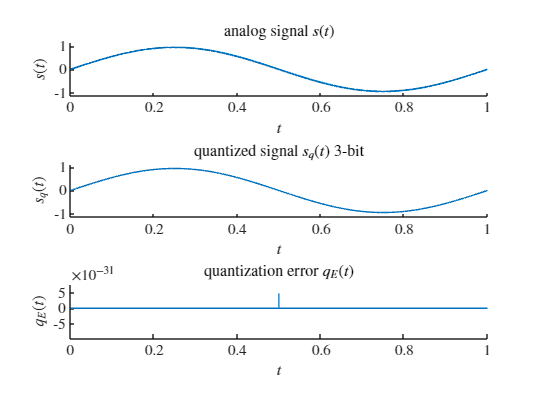

fig = figure; set(fig,'color','w');
subplot(3,1,1)
plot(t(1:N),s(1:N),'LineWidth',1);
title('analog signal $s(t)$');
ylabel('$s(t)$');
xlabel('$t$'); 
axis([0 N*dt min(s)*1.2 max(s)*1.2]);
box off;
subplot(3,1,2)
plot(t(1:N),sq(1:N));
title('quantized signal $s_{q}(t)$ 3-bit');
ylabel('$s_{q}(t)$');
xlabel('$t$'); 
axis([0 N*dt min(sq)*1.2 max(sq)*1.2]);
box off;
subplot(3,1,3)
plot(t(1:N),qe(1:N))
title('quantization error $q_{E}(t)$');
ylabel('$q_{E}(t)$');
xlabel('$t$'); 
axis([0 N*dt min(qe)*1.2 max(qe)*1.2]);
box off;


fprintf('SQNR - %i-bit: \t%0.4f dB\n',bits,sqnr); 

SQNR - 100-bit: 	650.1763 dB


fprintf('SQNR (theoretisch) - %i-bit: \t%0.4f dB\n',bits,sqnr_c); 

SQNR (theoretisch) - 100-bit: 	603.7600 dB


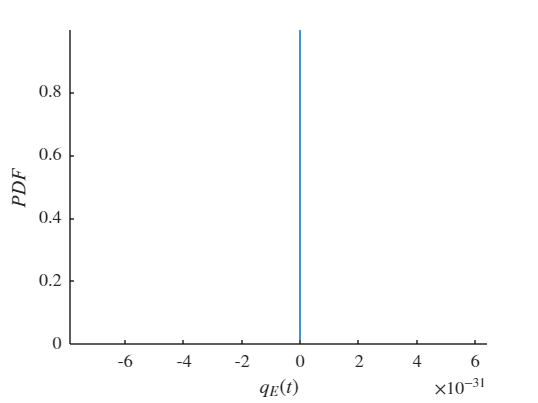

hist = figure;
set(hist,'color','w');
h = histogram(qe,'Normalization',"probability");  
h.FaceColor = [0 0.4470 0.7410];
h.EdgeColor = [0 0.4470 0.7410];
ylabel('$PDF$'); 
xlabel('$q_{E}(t)$'); 
box off; axis tight;


fprintf('Quantization steps size - %i-bit: \t%0.4f V\n',bits,qs); 

Quantization steps size - 100-bit: 	0.0000 V
